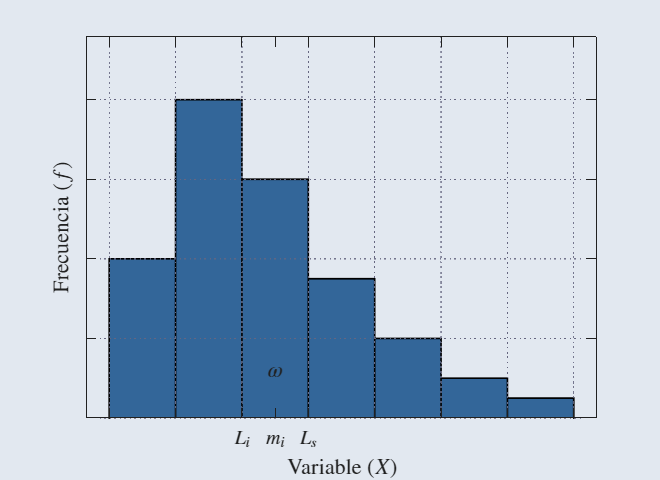

% Datos genéricos
datos = [163, 392, 269, 366, 605, 299, 287, 162, 222, 287, ...
         348, 405, 253, 159, 227, 483, 206, 273, 509, 141, ...
         319, 537, 211, 302, 483, 182, 294, 378, 344, 277, ...
         204, 284, 250, 280, 248, 425, 386, 234, 310, 224, ...
         273, 245, 339, 250, 275, 364, 262, 480, 197, 373];

k = 7;
ancho = 70;
limite_inf = 140;
bordes = limite_inf : ancho : (limite_inf + k*ancho);

% Color de fondo
color_fondo = [226 232 240] / 255;

% Figura base
figure('Color', color_fondo);
set(gcf, 'Units', 'inches', 'Position', [0 0 5.5 4]);

% Histograma
h = histogram(datos, bordes, 'FaceColor', [0.2 0.4 0.6], ...
    'FaceAlpha', 1, 'EdgeColor', 'black', 'LineWidth', 1);

ax = gca;

% Usar renderizador LaTeX para tipografía matemática estándar (Computer Modern)
set(ax, 'FontSize', 11, 'Color', 'none', 'FontName', 'Cambria');
xlabel('Variable ($X$)', 'Interpreter', 'latex');
ylabel('Frecuencia ($f$)', 'Interpreter', 'latex');

% Configuración del eje Y (ticks visibles sin valores)
ylim([0, max(h.Values) * 1.2]);
yticks(linspace(0, max(h.Values), 5));
yticklabels([]);

% Orientación interna de los ticks en ambos ejes
set(ax, 'TickDir', 'in', 'TickLength', [0.02 0.02]);

% Malla punteada solo en las fronteras de clase (bordes)
grid off;
hold on;
x_grid = repmat(bordes, 2, 1);
y_grid = repmat([0; max(h.Values)*1.2], 1, length(bordes));
line(x_grid, y_grid, 'Color', [0.4 0.4 0.5 0.5], 'LineStyle', ':');

y_ticks_val = linspace(0, max(h.Values), 5);
x_grid_h = repmat([bordes(1)-10; bordes(end)+10], 1, length(y_ticks_val));
y_grid_h = repmat(y_ticks_val, 2, 1);
line(x_grid_h, y_grid_h, 'Color', [0.4 0.4 0.5 0.5], 'LineStyle', ':');

box on;

% --- CONFIGURACIÓN EJE X (L_i, x_i, L_s) ---
x_mc = bordes(3) + ancho/2; 
y_mc = h.Values(3);        

posiciones_x = sort([bordes, x_mc]);
etiquetas_x = cell(1, length(posiciones_x));

for idx = 1:length(posiciones_x)
    if posiciones_x(idx) == bordes(3)
        etiquetas_x{idx} = '$L_i$';
    elseif posiciones_x(idx) == x_mc
        etiquetas_x{idx} = '$m_i$';
    elseif posiciones_x(idx) == bordes(4)
        etiquetas_x{idx} = '$L_s$';
    else
        etiquetas_x{idx} = '';
    end
end

xticks(posiciones_x);
xticklabels(etiquetas_x);
set(ax, 'TickLabelInterpreter', 'latex', 'FontSize', 12);

% --- ANOTACIÓN ANCHO DE CLASE (\omega) ---
%annotation('doublearrow', [0.46 0.54], [0.38 0.38], 'LineWidth', 1.0);
text(x_mc, y_mc/5, '$\omega$', 'Interpreter', 'latex', ...
    'FontSize', 13, 'HorizontalAlignment', 'center');

hold off;

% Exportación
set(gcf, 'Units', 'inches', 'Position', [0 0 5.5 4]);
exportgraphics(gcf, 'histogramscheme.png', 'Resolution', 300);